# Q1. Sequence Classification Using LSTM *(30 points)*

## 0. Importing Data

`XTrain` is a cell array containing 270 sequences of dimension 12 of varying length. `YTrain` is a categorical vector of labels "1","2",...,"9".

`XTest` is a cell array containing 370 sequences of dimension 12 of varying length. `YTest` is a categorical vector of labels "1","2",..."9".

clear;
load("sequenceData.mat")
whos

  Name          Size             Bytes  Class          Attributes

  XTest       370x1             584432  cell                     
  XTrain      270x1             438384  cell                     
  YTest       370x1               1326  categorical              
  YTrain      270x1               1226  categorical              



## 1. Data Preprocessing (7+3 = 10)

###     1.1. Sort the training data for padding (7)

      Sort the training data by sequence length to prevent the training process from adding too much padding. 

      Get the sequence lengths of the training data for each observation.

numobservation = height(XTrain)

numobservation = 270

sequenceLength = zeros(1,numobservation)

sequenceLength =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:numobservation
    sequenceData = XTrain{i};
    sequenceLength(i) = size(sequenceData, 2);
end

      Sort the training data by sequence length.

[sequenceLength_sorted, idx] = sort(sequenceLength, "ascend")

sequenceLength_sorted =      7     9     9    10    10    10    10    10    10    10    10    10    10    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12


idx =     69    74   270    89   124   126   140   148   150   211   215   236   264    50    71    87   122   125   129   131   213   214   216   217   225   227   229   250   251   258   263    54    57    64    75    78    79    82   123   146   147   149   186   212   220   221   226   228   230   242


XTrain = XTrain(idx)

XTrain = 270×1 cell 배열
    {12×7  double}
    {12×9  double}
    {12×9  double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×11 double}
    {12×11 double}
    {12×11 double}


YTrain = YTrain(idx)

YTrain = 270×1 categorical 배열
     3 
     3 
     9 
     3 
     5 
     5 
     5 
     5 
     5 
     8 
     8 
     8 
     9 
     2 
     3 
     3 
     5 
     5 
     5 
     5 
     8 
     8 
     8 
     8 
     8 
     8 
     8 
     9 
     9 
     9 


###     1.2. Display the sorted data (3)

      View the sorted sequence lengths in a bar chart. Display the plot as the figure in the right pane.

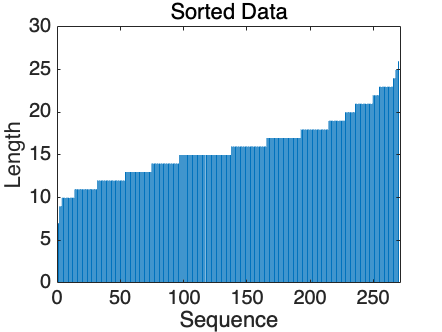

figure
bar(sequenceLength_sorted)
title("Sorted Data")
xlabel("Sequence")
ylabel("Length")

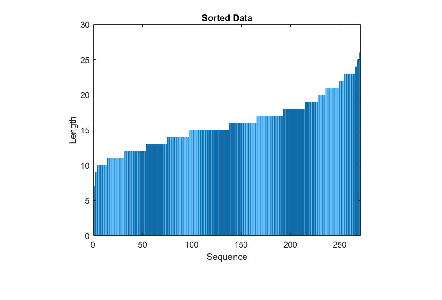

imshow(imread("Q2_sortedData.jpg"))

## 2. Creating LSTM Network (4)

Create a LSTM Network. **The number of hidden units is 100.**

layers = [sequenceInputLayer(12);
    bilstmLayer(100,"OutputMode","last");
    fullyConnectedLayer(9);
    softmaxLayer();
    classificationLayer()]

layers =   다음 계층을 포함한 5×1 Layer 배열:

     1   ''   시퀀스 입력   시퀀스 입력 (차원 12개)
     2   ''   BiLSTM      BiLSTM (은닉 유닛 100개)
     3   ''   완전 연결     9 완전 연결 계층
     4   ''   소프트맥스    소프트맥스
     5   ''   분류 출력     crossentropyex

## 3. Training Network (5+1 = 6)

###     3.1. Create training options (5)

      The training options you **SHOULD KEEP** are as follows. The rest of training options are tunerable.

- **Mini-batch size: Choose an appropriate mini-batch size based on ****1.2.**** results**

- **Sequence length: Longest**

- **Shuffle: Choose the right shuffle option**

- Max Epochs: 50

- Display training progress

opts = trainingOptions("adam" ,"MiniBatchSize",32,"SequenceLength","longest",...
    "Shuffle","never","MaxEpochs",50,"Plots","training-progress")

opts =   TrainingOptionsADAM - 속성 있음:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 50
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'never'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
  

###     3.2. Train Network (1)

단일 CPU에서 훈련합니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０３　｜　　　　　　　０．００％　｜　　　　　２．２２６７　｜　　　０．００１０　｜
｜　　　　　　　７　｜　　　　　　５０　｜　　　　　００：００：０５　｜　　　　　　８７．５０％　｜　　　　　０．７６８９　｜　　　０．００１０　｜
｜　　　　　　１３　｜　　　　　１００　｜　　　　　００：００：０８　｜　　　　　１００．００％　｜　　　　　０．０５９３　｜　　　０．００１０　｜
｜　　　　　　１９　｜　　　　　１５０　｜　　　　　００：００：１１　｜　　　　　　９６．８８％　｜　　　　　０．０６３４　｜　　　０．００１０　｜
｜　　　　　　２５　｜　　　　　２００　｜　　　　　００：００：１３　｜　　　　　１００．００％　｜　　　　　０．０１２８　｜　　　０．００１０　｜
｜　　　　　　３２　｜　　　　　２５０　｜　　　　　００：００：１６　｜　　　　　１００．００％　｜　　　　　０．００９２　｜　　　０．００１０　｜
｜　　　　　　３８　｜　　　　　３００　｜　　　　　００：００：１９　｜　　　　　１００．００％　｜　　　　　０．００３２　｜　　　０．００１０　｜
｜　　　　　　４４　｜　　　　　３５０　｜　　　　　００：００：２１　｜　　　　　１００．００％　｜　　　　　０．００１６　｜　　　０．００１０　｜
｜　　　　　　５０　｜　　　　　４００　｜　　　　　００：００：２４　｜　　　　　１００．００％　｜　　　　　０．００１３　｜　　　０．００１０　｜
｜＝＝＝＝＝＝＝＝

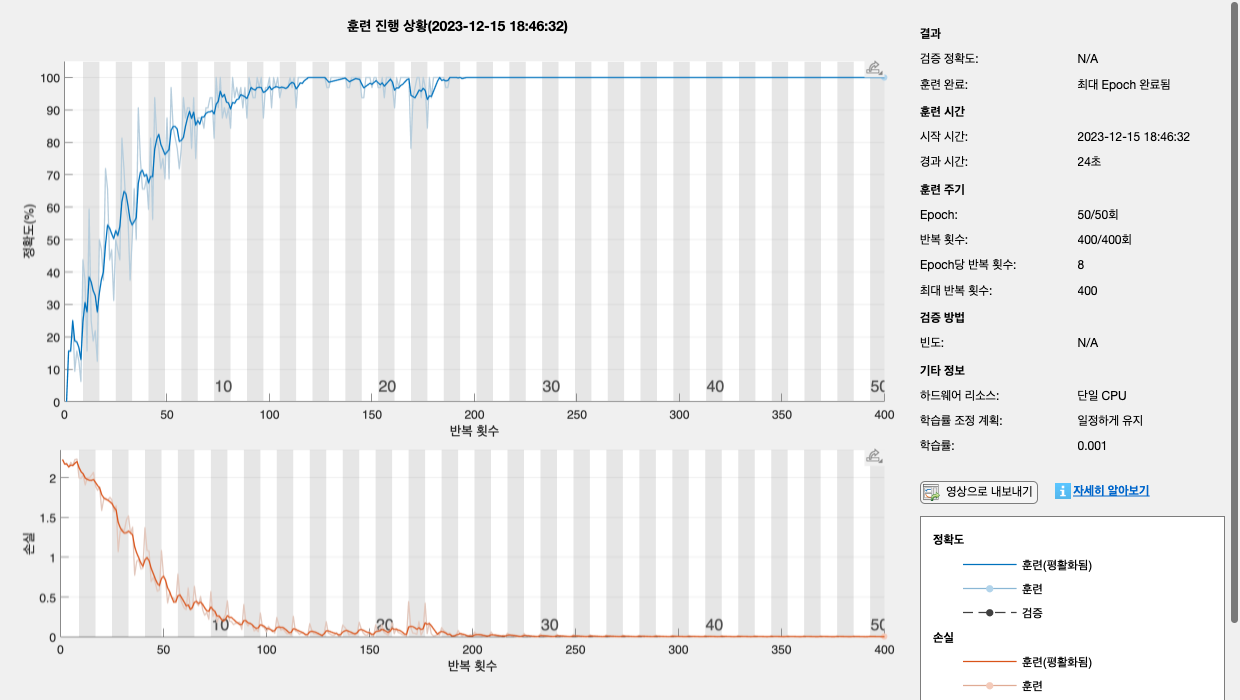

newnet =   SeriesNetwork - 속성 있음:

         Layers: [5×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}


newnet = trainNetwork(XTrain, YTrain, layers, opts)

## 4. Evaluating network (4+4+1+1 = 10)

The trained network used mini-batches of sequences of similar length. Ensure that the test data is organized in the same way. Sort the test data by sequence length.

###     4.1. Sort the test data for padding (4)

      Get the sequence lengths of the test data for each observation.

numobservation = height(XTest)

numobservation = 370

sequenceLength_test = zeros(1, numobservation)

sequenceLength_test =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:numobservation
    sequenceData_test = XTest{i};
    sequenceLength_test(i) = size(sequenceData_test, 2);
end

      Sort the test data by sequence length.

[sequenceLength_test_sorted, idx] = sort(sequenceLength_test, "ascend")

sequenceLength_test_sorted =      7     9     9     9     9     9     9     9     9    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11


idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


XTest = XTest(idx)

XTest = 370×1 cell 배열
    {12×7  double}
    {12×9  double}
    {12×9  double}
    {12×9  double}
    {12×9  double}
    {12×9  double}
    {12×9  double}
    {12×9  double}
    {12×9  double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}
    {12×10 double}


YTest = YTest(idx)

YTest = 370×1 categorical 배열
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     5 
     8 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     5 
     5 
     8 
     8 
     8 
     9 
     3 
     3 
     3 
     3 
     3 
     3 


###     4.2. Predict the labels of the test data (4)

pred = classify(newnet, XTest, "MiniBatchSize",32,"SequenceLength","longest")

pred = 370×1 categorical 배열
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     5 
     8 
     3 
     3 
     3 
     8 
     3 
     3 
     3 
     3 
     3 
     5 
     5 
     8 
     8 
     8 
     9 
     3 
     3 
     3 
     3 
     3 
     3 


###     4.3. Calculate the prediction accuracy (1)

Acc = nnz(pred == YTest)/numel(YTest)

Acc = 0.9757

###     4.4. Display a confusion chart (1)

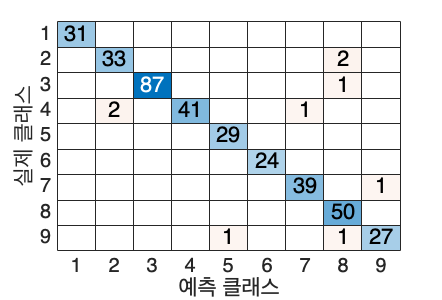

confusionchart(YTest,pred)